## Statistics

This notebook includes some exercises to related to statistics in MATLAB. Prepared for EAS Practical Coding and Math course at Georgia Tech.

### Calculate some relevant statistics for Atlanta temperatures

Load in and plot Atlanta mean August temperature data

data=load('ATL_MonMeanTemp_1879_2020.mat');
data = data.ATLtemp

data = 1.0e+03 *

    1.8790    0.0443    0.0437    0.0576    0.0589    0.0698    0.0749    0.0796    0.0739    0.0687    0.0643    0.0539    0.0515
    1.8800    0.0543    0.0514    0.0555    0.0634    0.0710    0.0765    0.0792    0.0768    0.0694    0.0608    0.0472    0.0421
    1.8810    0.0401    0.0466    0.0491    0.0591    0.0708    0.0778    0.0811    0.0788    0.0755    0.0672    0.0526    0.0496
    1.8820    0.0488    0.0524    0.0574    0.0648    0.0661    0.0766    0.0759    0.0758    0.0717    0.0658    0.0511    0.0414
    1.8830    0.0430    0.0502    0.0502    0.0616    0.0674    0.0764    0.0801    0.0762    0.0713    0.0660    0.0537    0.0480
    1.8840    0.0359    0.0517    0.0544    0.0584    0.0707    0.0711    0.0777    0.0753    0.0749    0.0681    0.0513    0.0445
    1.8850    0.0400    0.0392    0.0472    0.0610    0.0669    0.0766    0.0788    0.0771    0.0701    0.0570    0.0506    0.0428
    1.8860    0.0362    0.0418    0.0509    0.0609    0.0685    0

year = data(:,1)

year =         1879
        1880
        1881
        1882
        1883
        1884
        1885
        1886
        1887
        1888


augtemp = data(:,9)

augtemp =    73.9000
   76.8000
   78.8000
   75.8000
   76.2000
   75.3000
   77.1000
   77.3000
   76.5000
   78.5000


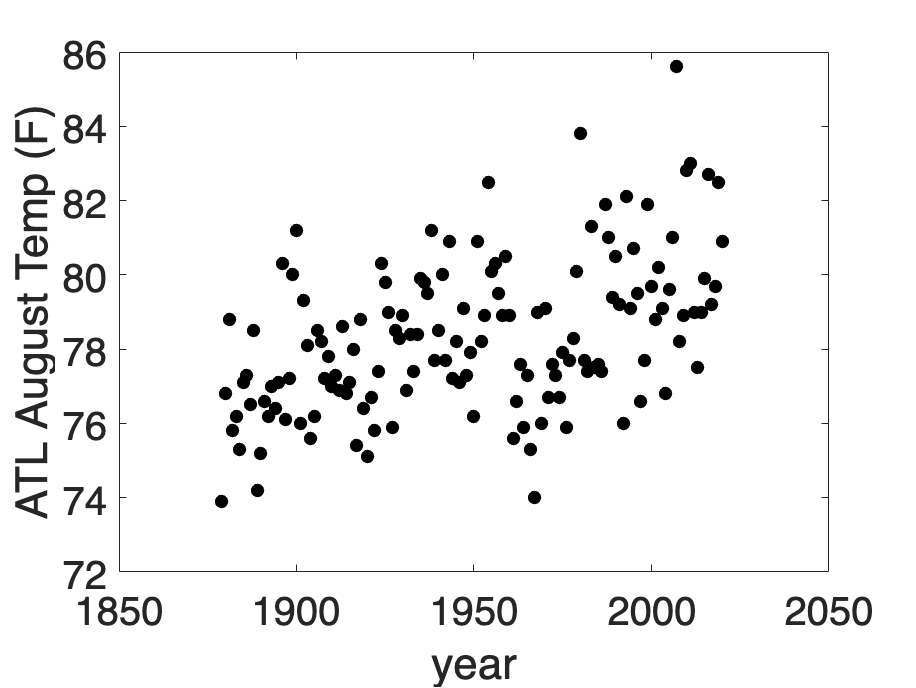

figure;plot(year,augtemp,'k.','markersize',20)
ylabel('ATL August Temp (F)','fontsize',20)
xlabel('year','fontsize',20)
set(gca,'fontsize',20)

Calculate the mean and median and Gaussian distribution

augtemp_mean = mean(augtemp)

augtemp_mean = 78.3352

augtemp_median = prctile(augtemp,50) %second input is percentile (median is 50th)

augtemp_median = 78.2000


temps = linspace(min(augtemp),max(augtemp),100);
augtemp_gauss = (1/(sqrt(2*pi)))*exp(-0.5*((temps-mean(augtemp))/std(augtemp)).^2);

Plot mean and median on a histogram

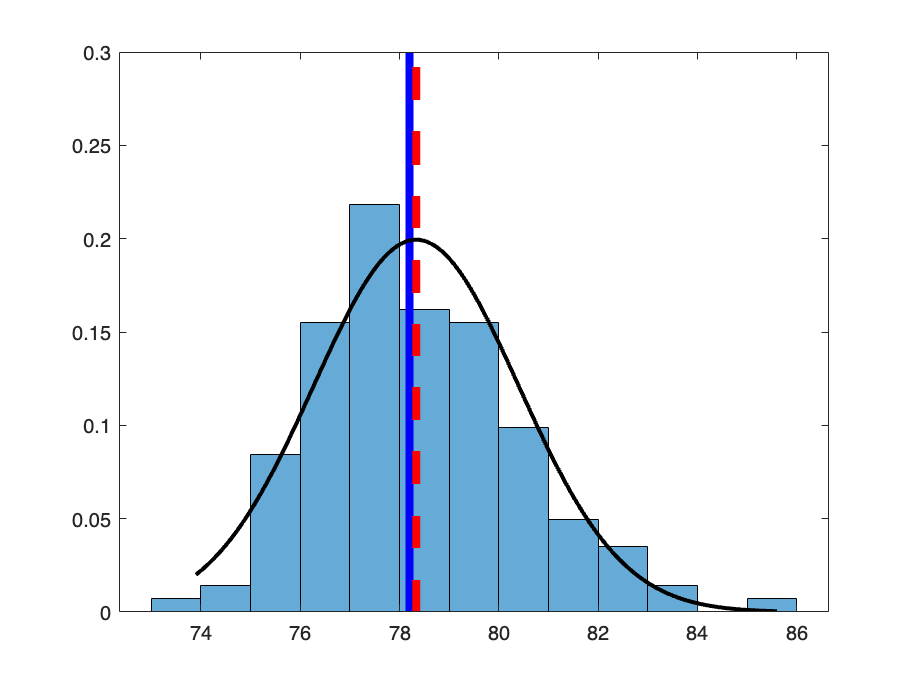

figure;
histogram(augtemp,'Normalization','probability');hold on
plot(augtemp_median.*ones(1,5),linspace(0,0.3,5),'b-','linewidth',4);
plot(augtemp_mean.*ones(1,5),linspace(0,0.3,5),'r--','linewidth',4);
plot(temps,augtemp_gauss./2,'k-','linewidth',2)

### Statistical inference

How to use statistics to answer questions:

*Science question*: Were the last 10 years  outside of the historical norm for August temperatures in ATL?

*Statistical question*: Can we reject the null hypothesis at a 95% confidence level that the mean of August temperatures over 2011-2020 was within the distribution of the historical average of Atlanta August temperatures?

nyr = 10;

tcrit = tinv(0.95,nyr-1)

tcrit = 1.8331

aug_recent = augtemp(end-nyr+1:end);
tval = (mean(aug_recent) - augtemp_mean)/(std(aug_recent)/sqrt(nyr-1))

tval = 3.2311

Because tval>tcrit, then we can reject the null hypothesis at the chosen confidence level. So, we can conclude at the 95% confidence interval that the average August temperature in Atlanta over the past 10 years is larger than the long-term average.

p=1-cdf('t',tval,nyr-1)

p = 0.0052

Indeed we can actually conclude that this 10-year mean would only be expected to occur 0.5% of the time if the long-term mean remained constant. We can conclude from this, that there is a high chance that the mean of the distribution has changed.